# Code for assessing local tuning biases in the mouse dLGN

## Processing Pipeline

First Prepare Data Files

Create an 'roi' data table

-  rows correspond to a lgn bouton in some imaging field

-  columns correspond some property of those rois. These properties include: imaging field ID, tuning kernel, retinotpoic kernel, orientation preference, spatial frequency preference, etc)

Create pair-wise distance table

- rows correspond to a pair of LGN boutons in some imaging field

-  columns correspond some property of that pair of boutn (retinotopic overlap, similarity of tuning kernel, etc)

Basic Analysis

- view the distribution of spatial frequency preferences, orientation preferences, of individual boutons

Main Analysis

- view the relationship betwen tuning similarity and receptive overlap for pairs of boutons

## Prepare Data Files

clear;
clc;
cd /Users/luis/Box/prjLGNTB/
addpath /Users/luis/Box/prjLGNTB/lgnDATA/   
addpath /Users/luis/Box/prjLGNTB/lgnANALYSIS/

lgn = lgnanz;
lgn.uif_tbl_base

these are all the unique  fields that were imaged. 9 total imaging sessions were conducted, from 4 different mice.

## Create an 'roi' (LGN bouton) data table 

uifs_to_process = [3 4];
lgn.get_roi_tables(uifs_to_process);

lgn.roi_stack_uif_list; % here are all all the imaging fields in the roi table
head(lgn.roi_stack) 
tail(lgn.roi_stack)

Now you have a table of rois 

- rows correspond to a lgn bouton in some imaging field

- columns correspond some property of those boutons. These properties include: imaging field ID, tuning kernel, retinotpoic kernel, orientation preference, spatial frequency preference, etc

Some Notes

- some rois have both tuning kernels AND receptive fields, while some have only one but not the other. This analysis only considers boutons with BOTH types of kernels

## Generate a bouton-pair 'distance' data table

lgn.get_distance_table(); 
head(lgn.dist_stack)    
tail(lgn.dist_stack)

Now you have a distance table

- rows correspond to a pair of LGN boutons in some imaging field

- columns correspond some property of that bouton pair (retinotopic overlap, similarity of tuning kernel, etc)

Basic Analysis

- view the distribution of spatial frequency preferences, orientation preferences, of individual boutons

## Main Analysis

### View the relationship betwen tuning similarity and receptive overlap for pairs of boutons

%% Linear Models
% figure(1)
clf;
%  Model the relationship between tuning similarity and RF overlap, for pairs of boutons in one imaging field

ans = 8×33 table
      mouse      uif    pair_roiDistMatIdx    pair_roiOrisfId    pair_roiHoughId    dRetKern_c2cDist    dRetKern_corr    dRetKern_corrStrong    dRetKern_corrWeak     dRetKern_Overlap     dRetKern_OverlapFiftyPrc    dRetKern_OverlapYes    dRetKern_OverlapNo      dTunKern_cos         dTunKern_corr            dSfResp              dLogSfEst         dLogSfEst_lessThanHalfOct    dLogSfEst_lessThanOneOct    dLogSfEst_lessThanTwoOct    dLogSfEst_lessThanThreeOct    dLogSfEst_AnyDiff    dLogSfEst_moreThanHalfOct    dLogSfEst_moreThanOneOct    dLogSfEst_moreThanTwoOct

uif  = lgn.roi_stack_uif_list(1);

ans = 8×33 table
      mouse      uif    pair_roiDistMatIdx    pair_roiOrisfId    pair_roiHoughId    dRetKern_c2cDist     dRetKern_corr    dRetKern_corrStrong    dRetKern_corrWeak     dRetKern_Overlap     dRetKern_OverlapFiftyPrc    dRetKern_OverlapYes    dRetKern_OverlapNo      dTunKern_cos         dTunKern_corr            dSfResp              dLogSfEst         dLogSfEst_lessThanHalfOct    dLogSfEst_lessThanOneOct    dLogSfEst_lessThanTwoOct    dLogSfEst_lessThanThreeOct    dLogSfEst_AnyDiff    dLogSfEst_moreThanHalfOct    dLogSfEst_moreThanOneOct    dLogSfEst_moreThanTwoOct</

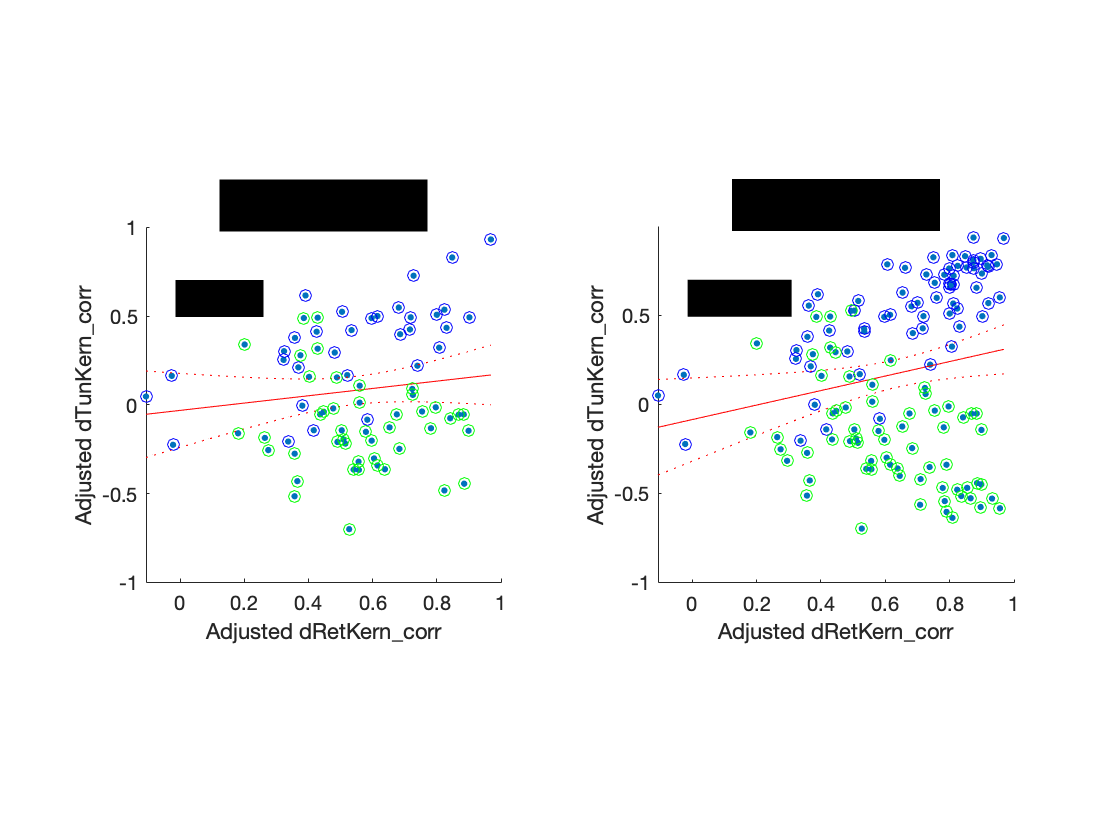

lgn.fit_plot_lm(uif);

% Run it again but this time with the entire data set, accross all imaging
% fielrs
uif_stack       = lgn.roi_stack_uif_list;
lgn.fit_plot_lm(uif_stack);

